This is a Matlab translation of a Mathematica code for Entanglement distillation. 

Authors of the original Mathematica code are Mariami Gachechiladze, Jan Nöller and Prabhav Jain.

Author of this Matlab code is Tomas Duchac.

**It is strongly recommended to run this live script with inline output!**

clear;clc;
%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Tensors functions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
tensor4 = @(a,b,c,d) kron(a,kron(b,kron(c,d)));
tensor3 = @(a,b,c) kron(a,kron(b,c));
tensor2 = @(a,b) kron(a,b);

%%%%%%%%%%%%%%%%% Partial Trace/Transpose Functions %%%%%%%%%%%%%%%%%
% Usage Example:
%		Suppose you have a qubit/qutrit/qubit system, so that p is a
%		12x12 density matrix. Then:
%
%			ptrace(p, n, [2 3 2]) traces out the n'th system
%			ptrace(p, [1 3], [2 3 2]) traces out both qubits
part_trace = @(a,b,c) ptrace(a,b,c);
part_transp = @(rho,sys,dim) Tx(rho,sys,dim);

%%%%%%%%%%% Transforming between product and Bell basis %%%%%%%%%%%
UBasisChange = 1/sym(sqrt(2))* [[1 0 1 0]; [0 1 0 1]; [0 1 0 -1]; [1 0 -1 0]];
ProdToBell = @(rho) simplify(UBasisChange' * rho * UBasisChange);
BellToProd = @(rho) simplify(UBasisChange * rho * UBasisChange');


%%%%%%%%%% Fidelity Functions %%%%%%%%%% 
Fidelity = @(rho_1, rho_2) trace(sqrtm(sqrtm(rho_1) * rho_2* sqrtm(rho_1)))^2;

Following functions correspond to $ketbra(a,b) = \left| a \rangle\langle b\right|$ and $inner(a,b) = \left\langle a | b\right\rangle$

ketbra = @(a,b) a*b';
inner = @(a,b) a'*b;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Definitions %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
zero_2x2 = sym([1;0]);
one_2x2  = sym([0;1]);

zero_3x3 = sym([1;0;0]);
one_3x3  = sym([0;1;0]);
two_3x3  = sym([0;0;1]);

zero_4x4 = sym([1;0;0;0]);
one_4x4  = sym([0;1;0;0]);
two_4x4  = sym([0;0;1;0]);
three_4x4= sym([0;0;0;1]);

const_1fsqr2 = sym(1/sqrt(2));
plus = const_1fsqr2*(zero_2x2 + one_2x2);
minus= const_1fsqr2*(zero_2x2 - one_2x2);

H_gate = const_1fsqr2 * [1 1; 1 -1];

%%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Pauli Matrices %%%%%%%%%%%%%%%%%%%%%%%%%%%%%%
X_gate   = sym([0 1; 1 0]);
Y_gate   = sym([0 -1i; 1i 0]);
Z_gate   = sym([1 0; 0 -1]);

P0 = eye(2);
PX = X_gate;
PY = Y_gate;
PZ = Z_gate;

%%%%%%%%%%%%%%%%%%%%%%%%%%%%% Rotation Matrices %%%%%%%%%%%%%%%%%%%%%%%%%%%%%
RX = @(Theta) simplify(expm(1i*Theta*PX/2));
RY = @(Theta) simplify(expm(1i*Theta*PY/2));
RZ = @(Theta) simplify(expm(1i*Theta*PZ/2));

%%%%%%%%%%%%%%%%%%%%%%%%% Bell States %%%%%%%%%%%%%%%%%%%%%%%%%
Bell_PHI_plus = const_1fsqr2 * (kron(zero_2x2,zero_2x2) + ...
                                kron(one_2x2,one_2x2) );
Bell_PHI_minus = const_1fsqr2 * (kron(zero_2x2,zero_2x2) - ...
                                kron(one_2x2,one_2x2) );
Bell_PSI_plus = const_1fsqr2 * (kron(zero_2x2,one_2x2) + ...
                                kron(one_2x2,zero_2x2) );
Bell_PSI_minus = const_1fsqr2 * (kron(zero_2x2,one_2x2) - ...
                                kron(one_2x2,zero_2x2) );

%%%%%%%%%%%%%%%%%%%%%%%%% Abbreviations %%%%%%%%%%%%%%%%%%%%%%%%% 
m = minus;
p = plus;
o = one_2x2;
oo = one_3x3;
oooo = tensor4(o,o,o,o);
z = zero_2x2;
oozz = tensor4(o,o,z,z);
zzoo = tensor4(z,z,o,o);
zzzz = tensor4(z,z,z,z);
zz = zero_3x3;

%%%%%%%%%%%%%%%%%%% Symbolics %%%%%%%%%%%%%%%%%%%
syms c00 c01 c02 c03 c10 c11 c12 c13 c20 c21 c22 c23 c30 c31 c32 c33 F x
holder_fx = x;

# **Entanglement Distillation Protocol**

Throughout this file, we will change our representation from the product basis to the Bell basis and vice versa, here is a small example for illustration. We know the usual Bell state whose density matrix looks as follows,

rho_Bell = sym( 1/2 * [[1 0 0 1]; [0 0 0 0]; [0 0 0 0]; [1 0 0 1]] )

$$rho\_Bell = \left(\begin{array}{cccc} \frac{1}{2} & 0 & 0 & \frac{1}{2}\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ \frac{1}{2} & 0 & 0 & \frac{1}{2} \end{array}\right)$$

we now change the basis from product basis to the Bell basis

ProdToBell(rho_Bell)

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

we notice that in Bell basis, the density matrix takes the usual representation as a projector and we can see that it is manifestly rank-1.

# Step 1 | Picking a suitable state

## Checking Fidelity

We write down the density matrix for the initial state and the singlet Bell state.

rho_Singlet = sym( 1/2 * [[0 0 0 0]; [0 1 -1 0]; [0 -1 1 0]; [0 0 0 0]] );
rho_1 = sym([[0 0 0 0]; [0 1/3 -1/4 0]; [0 -1/4 2/3 0]; [0 0 0 0]]);
Fidelity(rho_Singlet, rho_1)

$$ans = \frac{3}{4}$$

we see that this is greater than 1/2 and thus can be used for the distillation protocol.

# Step 2 | Diagonalizing the state

We consider a general density matrix

rho_Gen = [[c00 c01 c02 c03]; [c10 c11 c12 c13]; [c20 c21 c22 c23]; [c30 c31 c32 c33]]

$$rho\_Gen = \left(\begin{array}{cccc} c_{00} & c_{01} & c_{02} & c_{03}\\ c_{10} & c_{11} & c_{12} & c_{13}\\ c_{20} & c_{21} & c_{22} & c_{23}\\ c_{30} & c_{31} & c_{32} & c_{33} \end{array}\right)$$

now we act on the above state with each of the four Pauli operators bilaterally (i.e. $X \otimes X$) with a probability 1/4 each, thus the resulting state is

rho_2 = 1/4 * ((tensor2(P0, P0) * rho_Gen * tensor2(P0, P0)) + ...
               (tensor2(PX, PX) * rho_Gen * tensor2(PX, PX)) + ...
               (tensor2(PY, PY) * rho_Gen * tensor2(PY, PY)) + ...
               (tensor2(PZ, PZ) * rho_Gen * tensor2(PZ, PZ)))

$$rho\_2 = \left(\begin{array}{cccc} \frac{c_{00}}{2}+\frac{c_{33}}{2} & 0 & 0 & \frac{c_{03}}{2}+\frac{c_{30}}{2}\\ 0 & \frac{c_{11}}{2}+\frac{c_{22}}{2} & \frac{c_{12}}{2}+\frac{c_{21}}{2} & 0\\ 0 & \frac{c_{12}}{2}+\frac{c_{21}}{2} & \frac{c_{11}}{2}+\frac{c_{22}}{2} & 0\\ \frac{c_{03}}{2}+\frac{c_{30}}{2} & 0 & 0 & \frac{c_{00}}{2}+\frac{c_{33}}{2} \end{array}\right)$$

the above representation is in the product basis, when we move to the Bell basis, we see that the matrix indeed has a diagonal form

rho_D = simplify(ProdToBell(rho_2))

$$rho\_D = \left(\begin{array}{cccc} \frac{c_{00}}{2}+\frac{c_{03}}{2}+\frac{c_{30}}{2}+\frac{c_{33}}{2} & 0 & 0 & 0\\ 0 & \frac{c_{11}}{2}+\frac{c_{12}}{2}+\frac{c_{21}}{2}+\frac{c_{22}}{2} & 0 & 0\\ 0 & 0 & \frac{c_{00}}{2}-\frac{c_{03}}{2}-\frac{c_{30}}{2}+\frac{c_{33}}{2} & 0\\ 0 & 0 & 0 & \frac{c_{11}}{2}-\frac{c_{12}}{2}-\frac{c_{21}}{2}+\frac{c_{22}}{2} \end{array}\right)$$

# Step 3 | Applying Rotations

We now take the state obtained in the previous step and act it with the rotation operators $R_X, R_Y, R_Z$ with a probability 1/3  each, which transforms the state to

rho_3 = 1/3 * (tensor2(RX(pi/2), RX(pi/2)) * rho_2 * tensor2(RX(pi/2)', RX(pi/2)') + ...
               tensor2(RY(pi/2), RY(pi/2)) * rho_2 * tensor2(RY(pi/2)', RY(pi/2)') + ...
               tensor2(RZ(pi/2), RZ(pi/2)) * rho_2 * tensor2(RZ(pi/2)', RZ(pi/2)'));

now in the Bell basis, the state looks like

rho_3Bell = ProdToBell(rho_3)

$$rho\_3Bell = \begin{array}{l} \left(\begin{array}{cccc} \sigma_{1} & 0 & 0 & 0\\ 0 & \sigma_{1} & 0 & 0\\ 0 & 0 & \sigma_{1} & 0\\ 0 & 0 & 0 & \frac{c_{11}}{2}-\frac{c_{12}}{2}-\frac{c_{21}}{2}+\frac{c_{22}}{2} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{c_{00}}{3}+\frac{c_{11}}{6}+\frac{c_{12}}{6}+\frac{c_{21}}{6}+\frac{c_{22}}{6}+\frac{c_{33}}{3} \end{array}$$

this expression can be simplified further since we know that since $tr(\rho) = 1$, we have

trace(rho_3Bell)

$$ans = c_{00}+c_{11}+c_{22}+c_{33}$$

and thus $c_{00} + c_{11} +c_{22} +c_{33}  =1$, we can now define$F = \frac{c_{11}-c_{12}-c_{21}+c_{22}}{2}$ and then the state simplifies to

rho_3Bell = subs(rho_3Bell, c12, -2*F-c21+c11+c22);
rho_3Bell = simplify(subs(rho_3Bell, c00, 1 - (c11+c22+c33)))

$$rho\_3Bell = \left(\begin{array}{cccc} \frac{1}{3}-\frac{F}{3} & 0 & 0 & 0\\ 0 & \frac{1}{3}-\frac{F}{3} & 0 & 0\\ 0 & 0 & \frac{1}{3}-\frac{F}{3} & 0\\ 0 & 0 & 0 & F \end{array}\right)$$

which is precisely the Werner state.

# Step 4 | Entangling copies of states

In the previous step we were able to show that any arbitrary state can be brought into the form of a Werner state

rho_WBell = rho_3Bell;
rho_W = BellToProd(rho_WBell);

on the above state, we act with the Pauli-Y gate on only one subsystem i.e. we act $U_Y = Y \otimes I$. This will  do the map $\left|\Psi^-\rangle\langle\Psi^-\right| \rightarrow \left|\Phi^+\rangle\langle\Phi^+\right|$

rho_W2 = simplify(tensor2(PY,P0) *  rho_W * tensor2(PY,P0)');

if we now calculate the fidelity with the Bell state $|\Phi^+\rangle\langle\Phi^+|$ we have

rho_Bell = 1/2 * [[1 0 0 1]; [0 0 0 0]; [0 0 0 0]; [1 0 0 1]];
Fidelity(rho_W2, rho_Bell)

$$ans = F$$

thus now we have the fidelity $F > \frac{1}{2}$ with the Bell state. We now consider the following unitary : $U_{i,j} = |0\rangle\langle 0|_i \otimes X_j + |1\rangle\langle 1|_i +I_j$ , take the state $\rho_{w_{12}} \otimes \rho_{w_{34}}$ and act it with $U_{13}\otimes U_{24}$.

U = (tensor4([1 0; 0 0],P0, PX, P0) + tensor4([0 0; 0 1], P0, P0, P0)) * ... 
    (tensor4(P0,[1 0; 0 0], P0, PX) + tensor4(P0, [0 0; 0 1], P0, P0));
rho_WF2 = simplify(U * tensor2(rho_W2, rho_W2) * U');

(it might be easier to do this and the next step manually on paper)

# Step 5 | Making measurements

Now we will make measurements in the $Z_3 \otimes Z_4$ basis and we are only interested in the cases where both the measurement outcomes are equal. We define the projectors corresponding to $|00\rangle \text{ and } |11\rangle$ as follows,

Proj00 = tensor4(P0, P0, [[1 0]; [0 0]], [[1 0]; [0 0]]);
Proj11 = tensor4(P0, P0, [[0 0]; [0 1]], [[0 0]; [0 1]]);

thus the probability that both the outcomes are same is given by  $p = tr\left(|00\rangle\langle00|\;\rho_W^{\;\otimes2}\right) + tr\left(|11\rangle\langle11|\;\rho_W^{\;\otimes2}\right)$

p = expand(trace(Proj00 * rho_WF2) + trace(Proj11 * rho_WF2))

$$p = \frac{8\,F^{2}}{9}-\frac{4\,F}{9}+\frac{5}{9}$$

Thus the reduced state after the measurement depending we obtain $|00\rangle$ or $|11\rangle$ is,

rho_Reduced = (Proj00 * rho_WF2 * Proj00) / trace(Proj00 * rho_WF2);

# Step 6 | Calculating new fidelity

We now simply calculate the fidelity of the reduced state with the Bell state

NewF = simplify(Fidelity(rho_Reduced, tensor3(rho_Bell, P0,P0)))

$$NewF = \frac{10\,F^{2}-2\,F+1}{8\,F^{2}-4\,F+5}$$

we now plot this new fidelity $F'$ with respect to the old fidelity $F$ below.

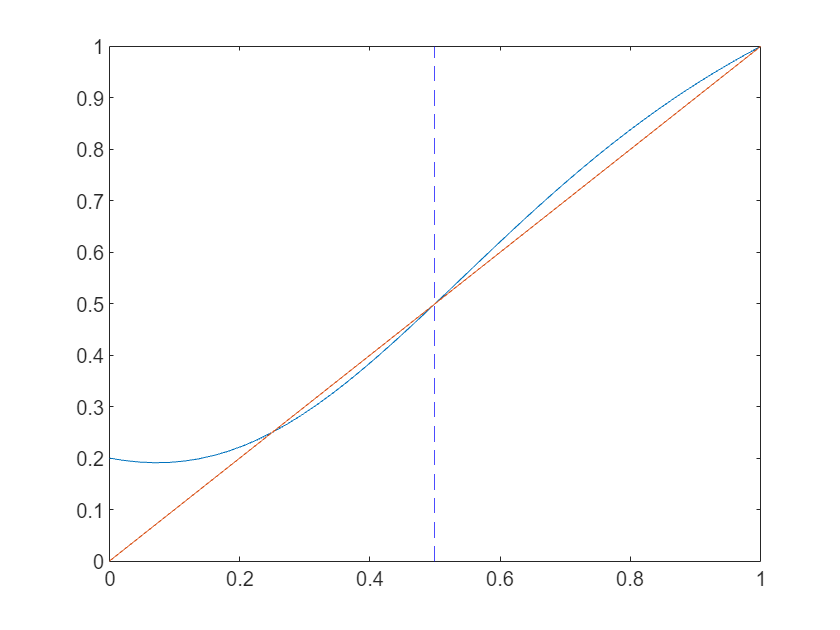

fplot(NewF,[0,1])
hold on
fplot(holder_fx,[0,1])
hold on
xline(0.5,'--b')

we see that if $F \geq \frac{1}{2}$ the graph of $F^{\prime }$ lies above $F$ and thus $F' \geq F$. Hence the fidelity is amplified and we can redo this procedure further amplifying the fidelity in each run and obtain states arbitrarily close to the Bell state.

% Functions for Partial Trace and Transpose

function x = ptrace(p, traceout, dims) % src: https://github.com/CoryGroup/quantum-utils-matlab/
    
	if any(traceout > length(dims)) || any(traceout < 0)
		error('Invalid subsystem in traceout')
	end
	if (length(dims) == 1 && mod(length(p)/dims,1) ~= 0) || length(p) ~= prod(dims)
		error('Size of state p inconsistent with dims');
	end

	traceout = setdiff(traceout,find(dims == 1));
	dims = dims(dims ~= 1);
	n = length(dims);
	rdim = dims(end:-1:1);
	keep = 1:n;
	keep(traceout) = [];
	dimtrace = prod(dims(traceout));
	dimkeep = length(p)/dimtrace;
	if any(size(p) == 1)
		if size(p,1) == 1
        end
		perm = n+1-[keep(end:-1:1),traceout];
		x = reshape(permute(reshape(p,rdim),perm),[dimkeep,dimtrace]);
		x = x*x';
    else
		perm = n+1-[keep(end:-1:1),keep(end:-1:1)-n,traceout,traceout-n];
		x = reshape(permute(reshape(p,[rdim,rdim]),perm), [dimkeep,dimkeep,dimtrace^2]);
		x = sum(x(:,:,1:dimtrace+1:dimtrace^2),3);
	end
end

function x = Tx(rho,sys,dim) % src: https://www.dr-qubit.org/matlab/Tx.m

n = length(dim);
d = size(rho);
perm = 1:2*n;
perm([n+1-sys,2*n+1-sys]) = perm([2*n+1-sys,n+1-sys]);
x = reshape(permute(reshape(rho,[dim(end:-1:1),dim(end:-1:1)]),perm),d);

end